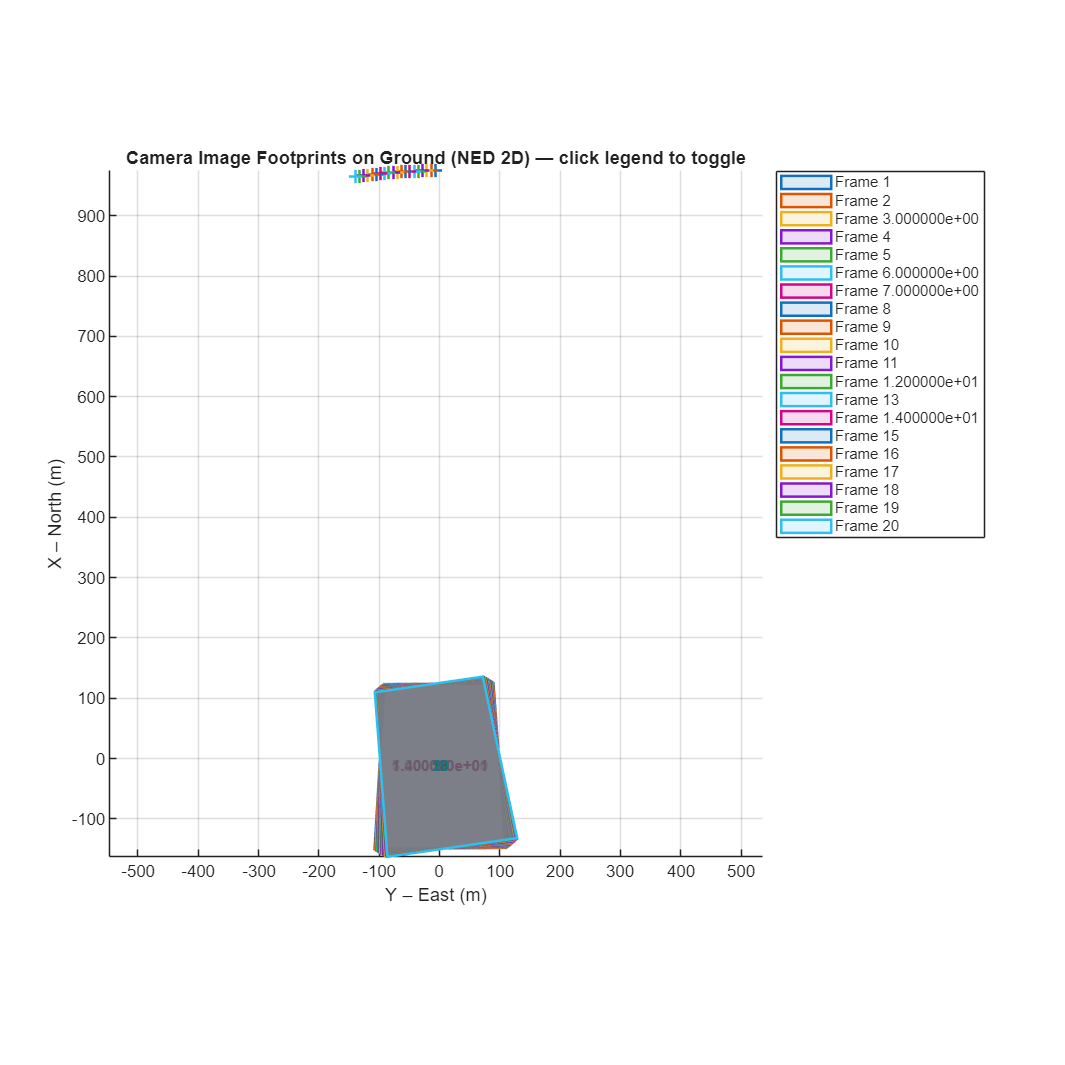

% Example dataset: [index, time, X(N), Y(E), Z(Down), Psi, Theta, Phi]  angles in radians

idx = out.logsout.getElement('subFrameIdx').Values.Data;
idx_running = out.logsout.getElement('subFrameRunningIdx').Values.Data;
time = out.logsout.getElement('t_at20Hz').Values.Data;
Position = out.logsout.getElement('cameraPosition').Values.Data;
Position = squeeze(Position);
Position = Position';
X = Position(:, 1);
Y = Position(:, 2);
Z = Position(:, 3);
Orientation = out.logsout.getElement('cameraPOSE').Values.Data;
Orientation = squeeze(Orientation);
Orientation = Orientation';
Psi = Orientation(:,1);
Theta = Orientation(:,2);
Phi = Orientation(:,3);

data = [idx_running time X Y Z Psi Theta Phi];
data = data(2:end, :);

% data = [
%     1,  0.0,   0,    0,  -120,  0.00,  0.15,  0.12;
%     2,  1.0,  15,   10,  -118,  0.10,  0.13, -0.11;
%     3,  2.0,  30,   25,  -115,  0.20,  0.16,  0.10;
% ];


visualize_camera_footprints(data, 1024, 1280, 38, 5, 0);

Table = table(idx, idx_running, time, X, Y, Z, Psi, Theta, Phi);
writetable(Table(2:end, :), 'pattern.txt')